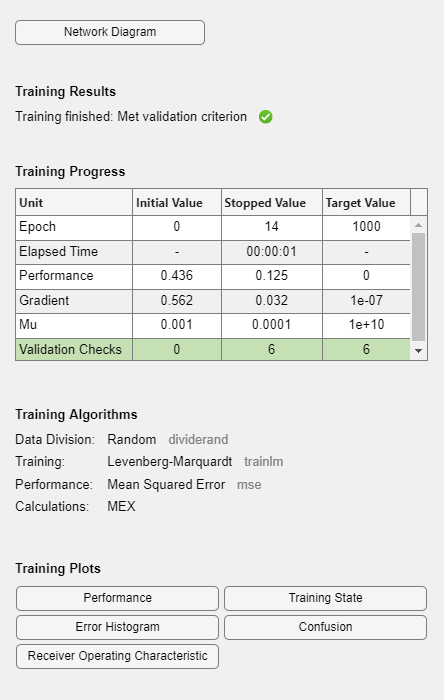

% Load and preprocess data
data = readtable('C:\Users\USER\Downloads\diabetes.csv');
X = table2array(data(:, 1:end-1));
Y = table2array(data(:, end));
X = normalize(X, 'range');

% Train/test split
cv = cvpartition(size(X,1), 'HoldOut', 0.3);
idx = cv.test;

XTrain = X(~idx, :)';
YTrain = Y(~idx)';
XTest = X(idx, :)';
YTest = Y(idx)';

% Convert labels to categorical target for MLP
YTrain_categorical = full(ind2vec(YTrain + 1)); % classes: 1 and 2

% Define and train MLP
net = patternnet([8 10]);
net.trainFcn = 'trainlm';
net.performFcn = 'crossentropy';

net.divideParam.trainRatio = 0.8;
net.divideParam.valRatio = 0.2;
net.divideParam.testRatio = 0.0;

[net, tr] = train(net, XTrain, YTrain_categorical);


% Predict on test data
YTest_output = net(XTest);
YTest_pred = vec2ind(YTest_output) - 1;

% Accuracy
accuracy = sum(YTest_pred == YTest) / length(YTest);
fprintf('MLP Accuracy: %.2f%%\n', accuracy * 100);

MLP Accuracy: 80.00%
